# Ecuaciones diferenciales implicitas

Para resolver este tipo de ecuaciones se usa el codigo

Se debe tener cuidado al momento de transformar la ecuación para el lenguja maquina. Aqui se transforma usando varibles de estado pero cambia la tecnica con la que se escribe

Antes y ahora


$$x\prime(1) = x(2) \;\;\; \to \;\;\; x\prime(1) - x(2) =0$$


y tambien


$$x\prime(i) \to xd(i)$$


Tambien se hara uso del algoritmo siguiente

Posteriormente, la ejecutamos la solucion como 

consideremos la siguiente ecuación diferencial implicita


$$u\prime_1 = u_3(t)$$



$$u\prime_2 = u_4(t)$$



$$2u\prime_3(t) + cos(u_1(t)-u_2(t))u\prime_4(t)= -g \sin (u_1(t)) - \sin ( u_1(t)-u_2(t))u^2_4(t)$$



$$\cos(u_1(t)-u_2(t))u_3\prime(t)+u_4\prime = - g \sin u_2(t)  + \sin(u_1(t)-u_2(t))u^2_3(t)$$


Con las siguientes condiciones iniciales


$$u_1(0) = 45, \;\; u_2(0) = 30, \;\; u_3(0) = u_4(0) = 0, \;\; g=9.81$$


en este problema, notamos que las ecuaciones  de estado ya estan definidas

Entonces, escribimos

g=9.81;
f=@(t,u,ud)[ud(1)-u(3);...
            ud(2)-u(4);...
            2*ud(3)+cos(u(1)-u(2))*ud(4)+g*sin(u(1))+sin(u(1)-u(2))*(u(4))^2;...
            cos(u(1)-u(2))*ud(3)+ud(4)+g*sin(u(2))+sin(u(1)-u(2))*(u(3))^2]

f = function_handle with value:
    @(t,u,ud)[ud(1)-u(3);ud(2)-u(4);2*ud(3)+cos(u(1)-u(2))*ud(4)+g*sin(u(1))+sin(u(1)-u(2))*(u(4))^2;cos(u(1)-u(2))*ud(3)+ud(4)+g*sin(u(2))+sin(u(1)-u(2))*(u(3))^2]


u0=[45,30,0,0]; ud0=rand(1,4); u0F=[1 1 1 1]; ud0F=[];
[u0,ud0]=decic(f,0,u0,u0F,ud0,ud0F) % compute compatible conditions

u0 =     45
    30
     0
     0


ud0 =    -0.0000
   -0.0000
   -0.6916
    9.1672


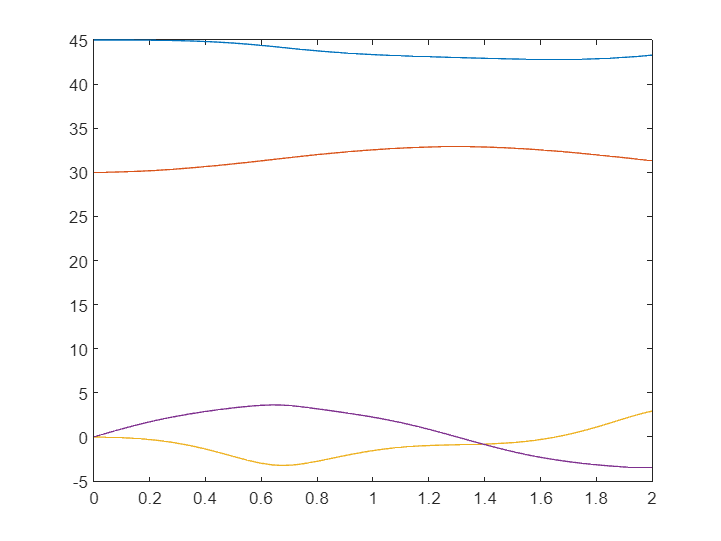

r=ode15i(f,[0,2],u0,ud0); plot(r.x,r.y)